# Analysis of Single-Channel Speech Enhancement Methods Using STFT: Spectral Subtraction, Wiener Filtering, and MMSE-STSA

## Introduction

Speech signals recorded in real-world environments are often degraded by additive background noise. The objective of speech enhancement is to improve the perceptual quality and intelligibility of noisy speech for human listeners and for automatic systems such as Automatic Speech Recognition (ASR).

This project implements and compares three classical single-channel speech enhancement algorithms:

- **Spectral Subtraction** (Boll, 1979)

- **Wiener Filtering**

- **MMSE Short-Time Spectral Amplitude (STSA) Estimator** (Ephraim & Malah, 1984)

All methods operate in the Short-Time Fourier Transform (STFT) domain, modifying the noisy magnitude spectrum while retaining the noisy phase for reconstruction.

The experiments compare results using both **objective metrics** (Signal-to-Noise Ratio, Segmental SNR, Spectral Flatness) and **qualitative analyses** (spectrogram and gain surface visualisations). The aim is to understand the trade-offs between simplicity, noise suppression strength, and perceptual quality across these traditional DSP methods.

## Theory and Literature Review

Speech enhancement assumes an additive noise model:


$$x\left(t\right)=s\left(t\right)+n\left(t\right)$$


where $s\left(t\right)$ is the clean speech signal and $n\left(t\right)$ is the additive noise. In the frequency domain, this becomes:


$$X\left(k,m\right)=S\left(k,m\right)+N\left(k,m\right)$$


Each enhancement algorithm estimates the clean spectral component $ˆS\left(k,m\right)$ from $X\left(k,m\right)$ using a frequency-dependent gain function $G\left(k,m\right)$:


$$ˆS\left(k,m\right)=G\left(k,m\right)X\left(k,m\right)$$


The clean speech signal is reconstructed through the inverse STFT:


$$\;ˆs\left(t\right)=\mathrm{iSTFT}\left\lbrace ˆS\left(k,m\right)\right\rbrace$$


This formulation underpins most modern enhancement algorithms. The core difference between methods lies in the definition and adaptation of the gain $\mathrm{𝐺}\left(\mathrm{𝑘},\mathrm{𝑚}\right)$.

### Spectral Subtraction

Spectral subtraction (Boll, 1979) is a deterministic noise suppression technique that subtracts an estimated noise magnitude from the noisy spectrum:


$$|ˆS\left(k,m\right)|=\max \left(|X\left(k,m\right)|-\alpha |ˆN\left(k\right)|,\beta |ˆN\left(k\right)|\right)$$


where:

- $\mathrm{𝛼}$ is the **over-subtraction factor** (typically >1), and

- $\beta$ is the **spectral floor constant** to prevent negative magnitudes.

The estimated clean spectrum is then reconstructed as:


$$ˆS\left(k,m\right)=|ˆS\left(k,m\right){|e}^{j\angle X\left(k,m\right)}$$


This method effectively reduces stationary noise but tends to introduce musical noise artifacts, characterised by random tonal bursts due to discontinuities in the magnitude spectrum.

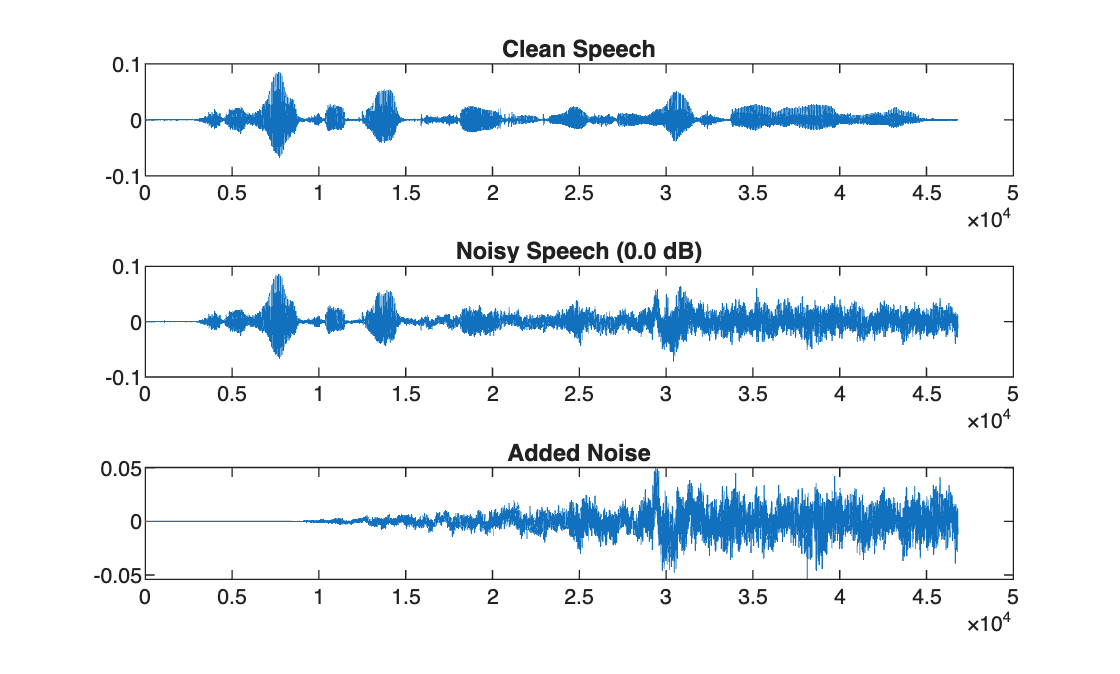

%% Experimental Setup
clc; clear; close all;

cleanFile = 'LDC93S1.wav';
noiseFile = 'sydney-airport-19612.wav';
snrIn = 0;                     % input SNR (dB)
alpha = 2.0; beta = 0.02;

[clean, fs] = audioread(cleanFile); clean = mean(clean,2);
[noise, fsN] = audioread(noiseFile); noise = mean(noise,2);
if fsN ~= fs, noise = resample(noise, fs, fsN); end

frameDur = 0.032; hopRatio = 0.5;
winLen = round(frameDur*fs);
hop = round(hopRatio*winLen);
nfft = 2^nextpow2(winLen);
win = hann(winLen,"periodic");

%% Generate Noisy Speech
[noisy, noise_used] = addNoiseAtSNR(clean, noise, snrIn);

figure;
subplot(3,1,1); plot(clean); title('Clean Speech');
subplot(3,1,2); plot(noisy); title(sprintf('Noisy Speech (%.1f dB)',snrIn));
subplot(3,1,3); plot(noise_used); title('Added Noise');


%% STFT Analysis
[S_noisy, f, t] = stft(noisy, fs, "Window", win, ...
    "OverlapLength", winLen-hop, "FFTLength", nfft);
mag_noisy = abs(S_noisy);
phase_noisy = angle(S_noisy);

% Estimate noise magnitude (oracle)
[S_noise, ~, ~] = stft(noise_used, fs, "Window", win, ...
    "OverlapLength", winLen-hop, "FFTLength", nfft);
N_mag = mean(abs(S_noise),2);

%% Spectral Subtraction Implementation
subtracted = mag_noisy - alpha*repmat(N_mag,1,size(mag_noisy,2));
mag_hat = max(subtracted, beta*repmat(N_mag,1,size(mag_noisy,2)));
S_hat_ss = mag_hat .* exp(1j*phase_noisy);
enhanced_ss = istft(S_hat_ss, fs, "Window", win, ...
    "OverlapLength", winLen-hop, "FFTLength", nfft);


### Wiener Filter Theory

Wiener filtering optimises the mean-square error between the clean and estimated spectra. It assumes known noise and signal statistics through *a posteriori* and *a priori* SNRs:

$\gamma \left(k,m\right)=\frac{\left|X\left(k,m\right){\left|\right.}^2 \right.}{\Phi_{\mathrm{nn}} \left(k,m\right)}$, $\xi \left(k,m\right)=\frac{\Phi_{\mathrm{ss}} \left(k,m\right)}{\Phi_{\mathrm{nn}} \left(k,m\right)}$�

The corresponding Wiener gain function is:

$G_W \left(k,m\right)=\frac{\xi \left(k,m\right)}{1+\xi \left(k,m\right)}$�

In practice, the *a priori* SNR is recursively estimated using the decision-directed approach (Ephraim & Malah, 1984):

$\xi \left(k,m\right)=\alpha_{\mathrm{DD}} \frac{\left|ˆS\left(k,m-1\right){\left|\right.}^2 \right.}{\Phi_{\mathrm{nn}} \left(k,m\right)}+\left(1-\alpha_{\mathrm{DD}} \right)\max \left(\gamma \left(k,m\right)-1,0\right)$,

which smooths gain adaptation across frames, reducing musical noise compared to direct subtraction.

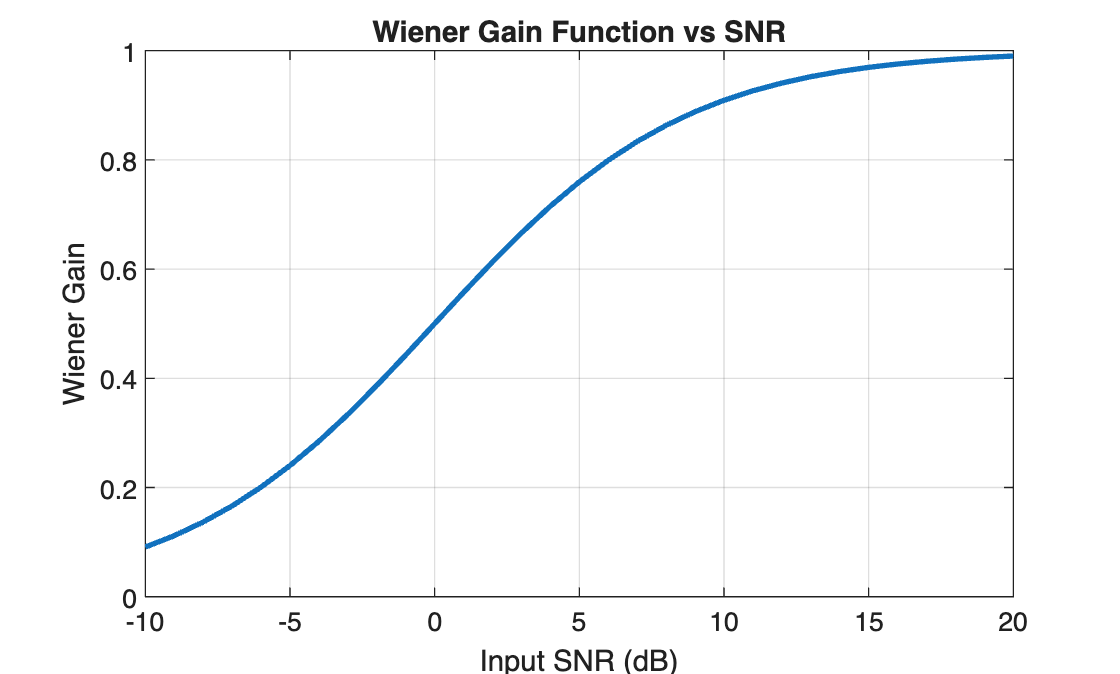

%% Wiener Filter Implementation
alphaDD = 0.98;                 % decision-directed factor
xi = zeros(size(mag_noisy));    % a priori SNR
gamma = (mag_noisy.^2)./(repmat(N_mag.^2,1,size(mag_noisy,2)));

% Initial frame
xi(:,1) = max(gamma(:,1)-1,0);
G_wiener = xi./(1+xi);

% Iterate through frames
for m = 2:size(mag_noisy,2)
    xi(:,m) = alphaDD*( (mag_noisy(:,m-1).^2)./(repmat(N_mag.^2,1,1)) ) ...
        + (1-alphaDD)*max(gamma(:,m)-1,0);
    G_wiener(:,m) = xi(:,m)./(1+xi(:,m));
end

S_hat_wiener = G_wiener .* S_noisy;
enhanced_wiener = istft(S_hat_wiener, fs, "Window", win, ...
    "OverlapLength", winLen-hop, "FFTLength", nfft);

%% Plot Gain vs Input SNR
snr_range = -10:20;
xi_demo = 10.^(snr_range/10);
G_demo = xi_demo./(1+xi_demo);
figure; plot(snr_range,G_demo,'LineWidth',2);
xlabel('Input SNR (dB)'); ylabel('Wiener Gain'); grid on;
title('Wiener Gain Function vs SNR');

### MMSE-STSA Theory (Ephraim & Malah, 1984)

The Minimum Mean-Square Error Short-Time Spectral Amplitude (MMSE-STSA) estimator takes a different approach: rather than minimising the error on the power spectrum, it directly minimises the mean-square error of the spectral amplitude, which is more closely related to human perception.

As in the Wiener case, the method uses the a posteriori SNR $\gamma \left(k,m\right)$ and the priori SNR $\xi \left(k,m\right)$:

$\gamma \left(k,m\right)=\frac{\left|X\left(k,m\right){\left|\right.}^2 \right.}{\Phi_{\mathrm{nn}} \left(k,m\right)}$, $\xi \left(k,m\right)=\frac{\Phi_{\mathrm{ss}} \left(k,m\right)}{\Phi_{\mathrm{nn}} \left(k,m\right)}$.

The a priori SNR is again obtained with the decision-directed estimator:

$\xi \left(k,m\right)=\alpha_{\mathrm{DD}} \frac{\left|ˆS\left(k,m-1\right){\left|\right.}^2 \right.}{\Phi_{\mathrm{nn}} \left(k,m\right)}+\left(1-\alpha_{\mathrm{DD}} \right)\max \left(\gamma \left(k,m\right)-1,0\right)$.

An intermediate variable


$$v\left(k,m\right)=\frac{\gamma \left(k,m\right)\xi \left(k,m\right)}{1+\xi \left(k,m\right)}$$


is then formed, and the optimal MMSE-STSA gain can be written as

$G_{\mathrm{MMSE}} \left(k,m\right)=\frac{\sqrt{\pi }}{2\sqrt{v\left(k,m\right)}}\exp \left(-\frac{v\left(k,m\right)}{2}\right)\left\lbrack \left(1+v\left(k,m\right)\right)I_0 \left(\frac{v\left(k,m\right)}{2}\right)+v\left(k,m\right)I_1 \left(\frac{v\left(k,m\right)}{2}\right)\right\rbrack \frac{1}{\gamma \left(k,m\right)}$,

where $I_0$ and $I_1$are modified Bessel functions of the first kind.

This nonlinear gain provides soft suppression in low-SNR regions and avoids the hard spectral clipping of spectral subtraction. Combined with the decision-directed SNR estimate, MMSE-STSA yields smoother temporal evolution of the gain, reduced musical noise, and better preservation of speech harmonics, especially in voiced segments.

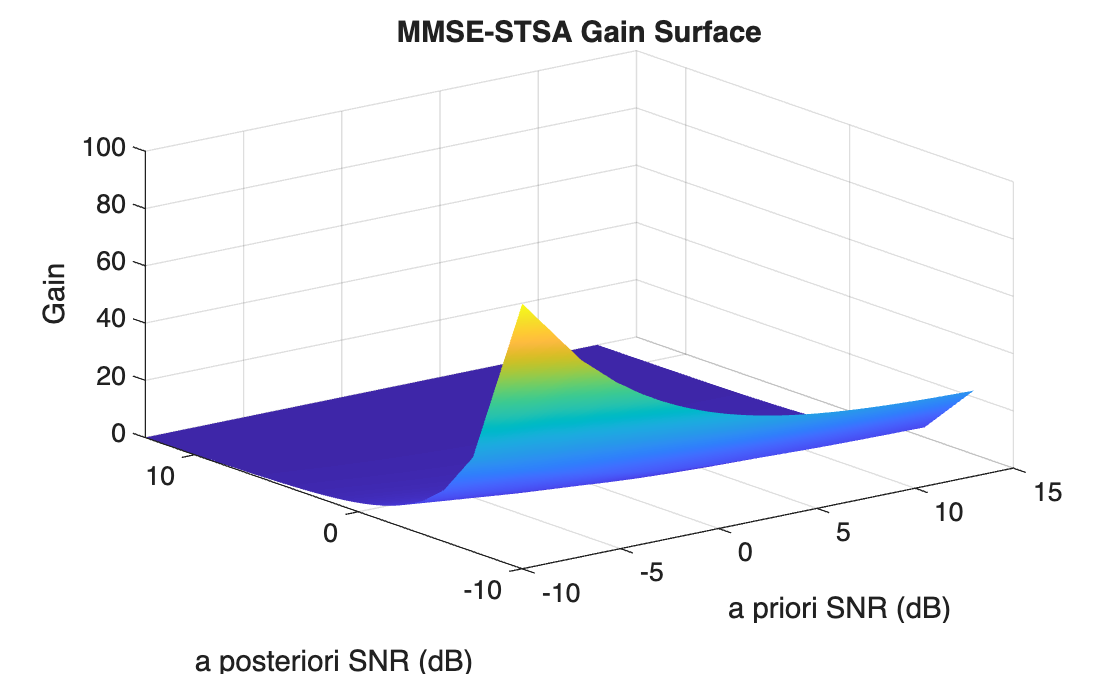

% %% MMSE-STSA Implementation
gamma = max(gamma, 1e-12);
xi    = max(xi,    1e-12);
v  = (gamma .* xi) ./ (1 + xi);
vf = max(v, 1e-12);
x  = vf/2;
I0s = besseli(0, x, 1);   % scaled
I1s = besseli(1, x, 1);   % scaled
comb = (1 + vf) .* I0s + vf .* I1s;
A = (sqrt(pi)/2) .* sqrt(vf) .* comb;
G_mmse = A ./ (gamma + eps);
G_mmse(~isfinite(G_mmse)) = 0;

S_hat_mmse    = G_mmse .* S_noisy;
enhanced_mmse = istft(S_hat_mmse, fs, "Window", win, ...
    "OverlapLength", winLen - hop, "FFTLength", nfft);

%% 3D Comparison of Gain Functions
snrLin = linspace(0,20,200);
xiLin = linspace(0,20,200);
[XI,GAM] = meshgrid(xiLin, snrLin);
V  = (GAM.*XI)./(1+XI);
G_M = (sqrt(pi)./(2*sqrt(V))) .* ((1+V).*besseli(0,V/2) + V.*besseli(1,V/2)) ...
    .* exp(-V/2)./(GAM+eps);

figure;
surf(10*log10(XI), 10*log10(GAM), G_M); shading interp;
xlabel('a priori SNR (dB)'); ylabel('a posteriori SNR (dB)');
zlabel('Gain'); title('MMSE-STSA Gain Surface');

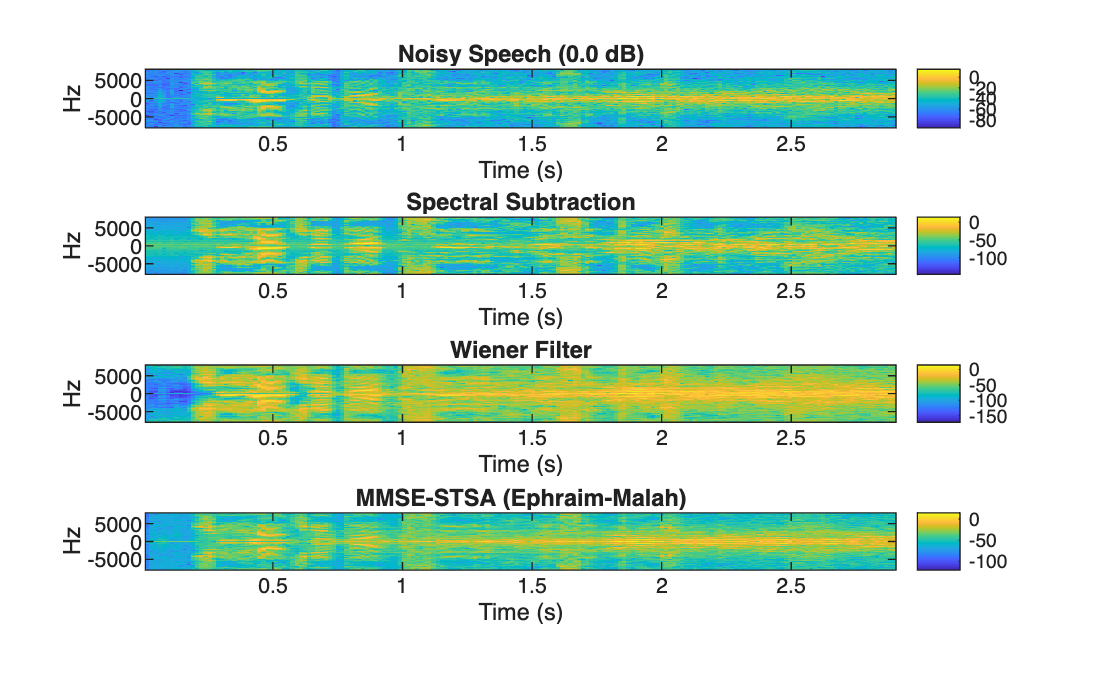


%% Results Comparison (Spectrograms)
figure('Name','Spectrogram Comparison','NumberTitle','off');

subplot(4,1,1);
safeSpecPlot(noisy, fs, winLen, hop, nfft);
title(sprintf('Noisy Speech (%.1f dB)', snrIn));

subplot(4,1,2);
safeSpecPlot(enhanced_ss, fs, winLen, hop, nfft);
title('Spectral Subtraction');

subplot(4,1,3);
safeSpecPlot(enhanced_wiener, fs, winLen, hop, nfft);
title('Wiener Filter');

subplot(4,1,4);
safeSpecPlot(enhanced_mmse, fs, winLen, hop, nfft);
title('MMSE-STSA (Ephraim-Malah)');


%% Objective Evaluation
clean = clean(1:min(length(clean),length(enhanced_mmse)));
noisy = noisy(1:length(clean));
snr_input  = computeSNR(clean, noisy-clean);
snr_ss     = computeSNR(clean, clean-enhanced_ss(1:length(clean)));
snr_wiener = computeSNR(clean, clean-enhanced_wiener(1:length(clean)));
snr_mmse   = computeSNR(clean, clean-enhanced_mmse(1:length(clean)));
fprintf('\n=== SNR Summary ===\nInput: %.2f dB\nSpectral Subtraction: %.2f dB\nWiener: %.2f dB\nMMSE-STSA: %.2f dB\n', ...
    snr_input, snr_ss, snr_wiener, snr_mmse);


=== SNR Summary ===
Input: 0.04 dB
Spectral Subtraction: -4.69 dB
Wiener: -23.74 dB
MMSE-STSA: -22.40 dB



%% Framewise (Segmental) SNR over Time
frameLenSeg = round(0.02*fs);      % 20 ms
hopSeg      = frameLenSeg;         % non-overlap for clarity
[segNoisy,tSeg]  = localSegSNR(clean,noisy,frameLenSeg,hopSeg,fs);
[segSS,~]        = localSegSNR(clean,enhanced_ss,frameLenSeg,hopSeg,fs);
[segWF,~]        = localSegSNR(clean,enhanced_wiener,frameLenSeg,hopSeg,fs);
[segMMSE,~]      = localSegSNR(clean,enhanced_mmse,frameLenSeg,hopSeg,fs);

figure('Name','Framewise (Segmental) SNR');
plot(tSeg, segNoisy, 'LineWidth',1); hold on;
plot(tSeg, segSS, 'LineWidth',1.5);

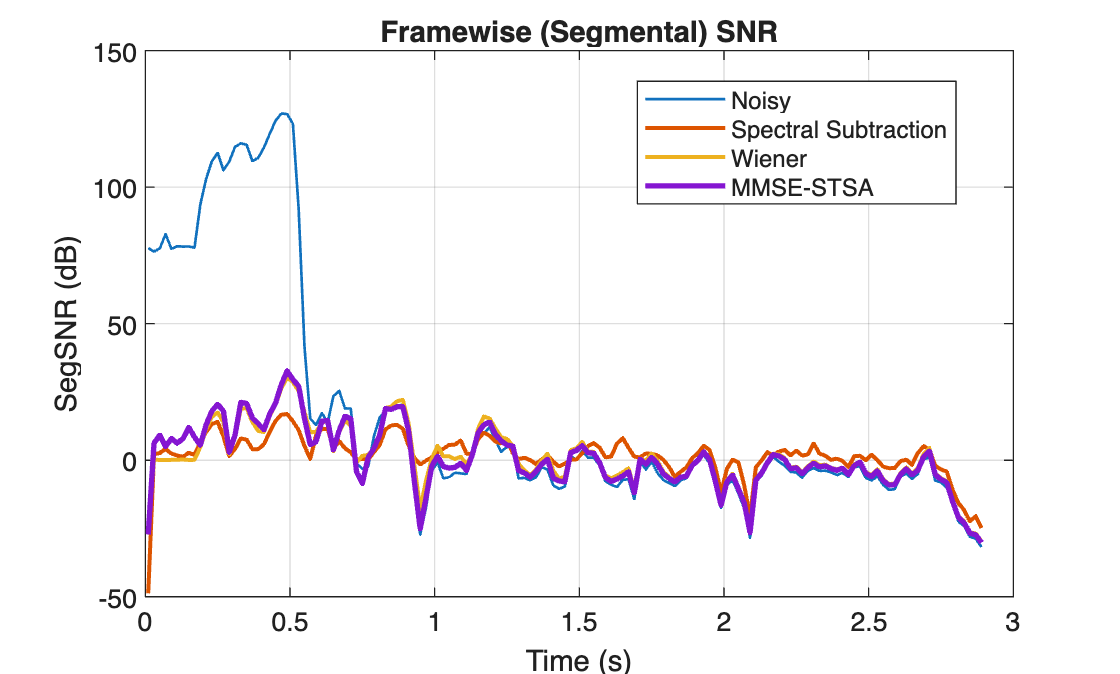

plot(tSeg, segWF, 'LineWidth',1.5);
plot(tSeg, segMMSE, 'LineWidth',2);
grid on; xlabel('Time (s)'); ylabel('SegSNR (dB)');
legend('Noisy','Spectral Subtraction','Wiener','MMSE-STSA','Location','best');
title('Framewise (Segmental) SNR');

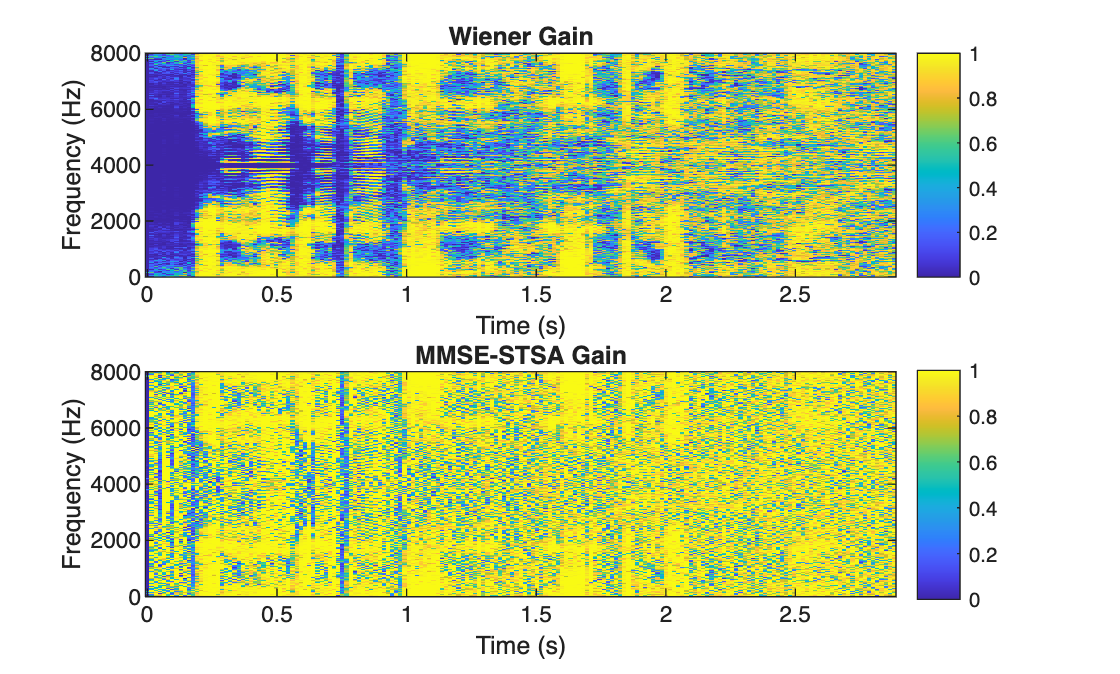


%% Gain Heatmaps (Time-Frequency)
figure('Name','Gain Heatmaps','NumberTitle','off');
tAxis = (0:size(G_wiener,2)-1)*hop/fs;
fAxis = (0:size(G_wiener,1)-1)*(fs/2/(size(G_wiener,1)-1));

subplot(2,1,1);
imagesc(tAxis, fAxis, G_wiener); axis xy; colorbar; caxis([0 1]);
xlabel('Time (s)'); ylabel('Frequency (Hz)'); title('Wiener Gain');

subplot(2,1,2);
imagesc(tAxis, fAxis, G_mmse); axis xy; colorbar; caxis([0 1]);
xlabel('Time (s)'); ylabel('Frequency (Hz)'); title('MMSE-STSA Gain');

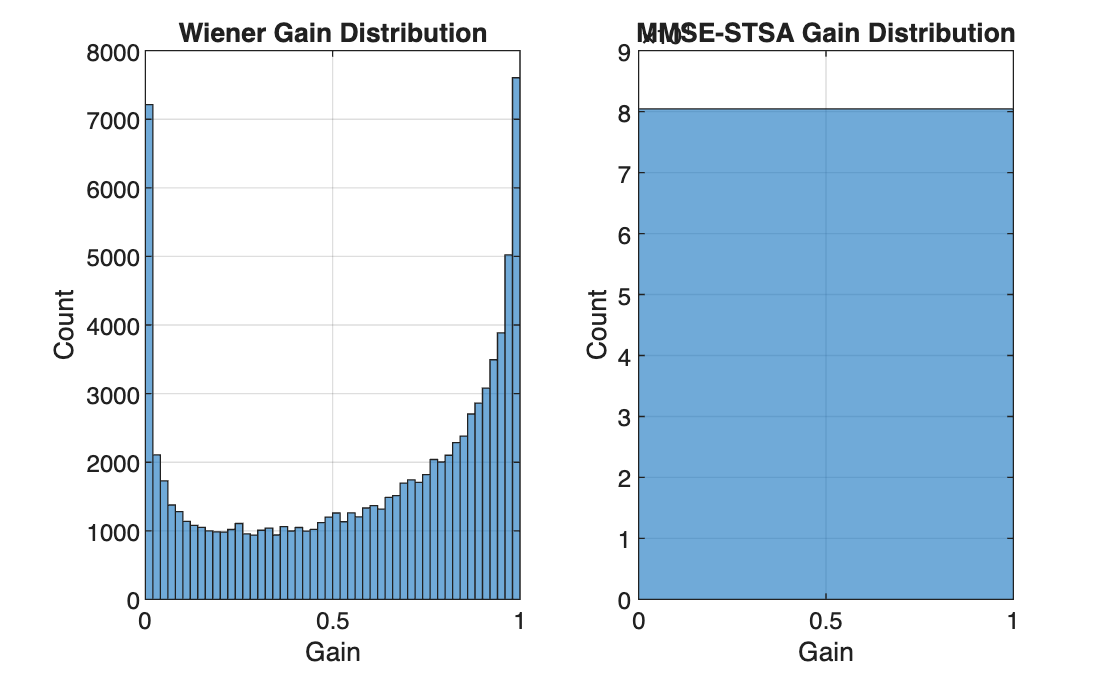


%% Gain Distributions (Histograms)
figure('Name','Gain Histograms');
subplot(1,2,1); histogram(G_wiener(:), 50); xlim([0 1]); grid on;
title('Wiener Gain Distribution'); xlabel('Gain'); ylabel('Count');
subplot(1,2,2); histogram(G_mmse(:), 50); xlim([0 1]); grid on;
title('MMSE-STSA Gain Distribution'); xlabel('Gain'); ylabel('Count');

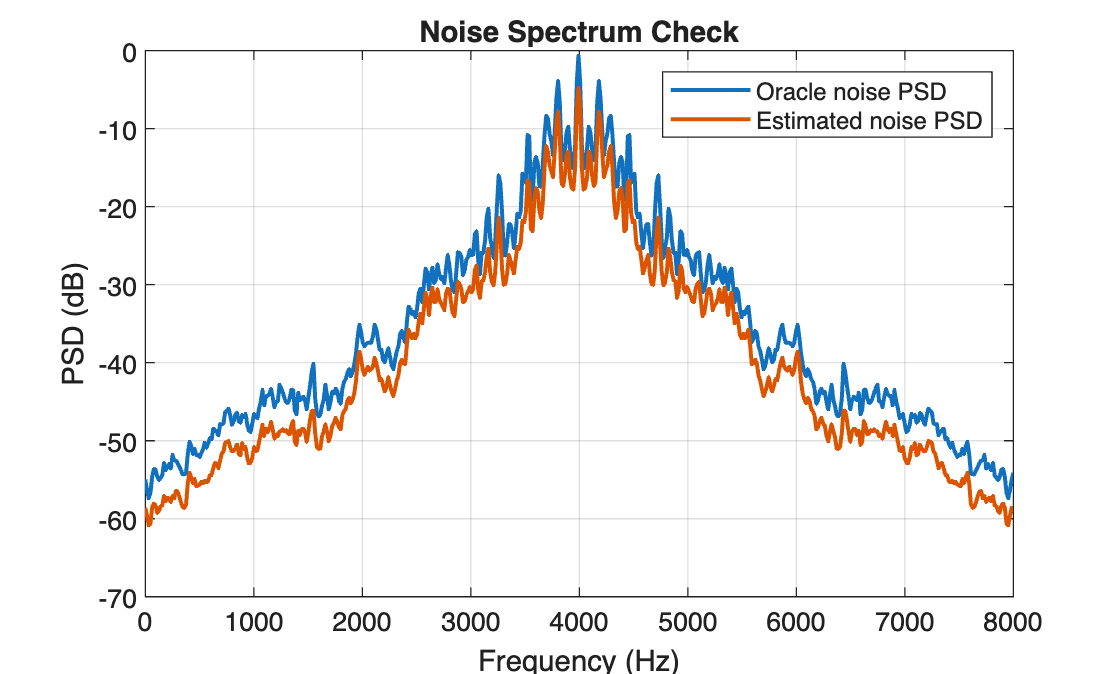


%% Noise PSD: Oracle vs Estimate
[S_noise_oracle,~,~] = stft(noise_used, fs, "Window", win, ...
    "OverlapLength", winLen - hop, "FFTLength", nfft);
Phi_nn_oracle = mean(abs(S_noise_oracle).^2, 2);
Phi_nn_est    = (N_mag.^2);

fAxisPSD = (0:numel(Phi_nn_est)-1)*(fs/2/(numel(Phi_nn_est)-1));
figure('Name','Noise PSD Comparison');
plot(fAxisPSD, 10*log10(Phi_nn_oracle+eps), 'LineWidth',1.5); hold on;
plot(fAxisPSD, 10*log10(Phi_nn_est+eps), 'LineWidth',1.5);
grid on; xlabel('Frequency (Hz)'); ylabel('PSD (dB)');
legend('Oracle noise PSD','Estimated noise PSD'); title('Noise Spectrum Check');

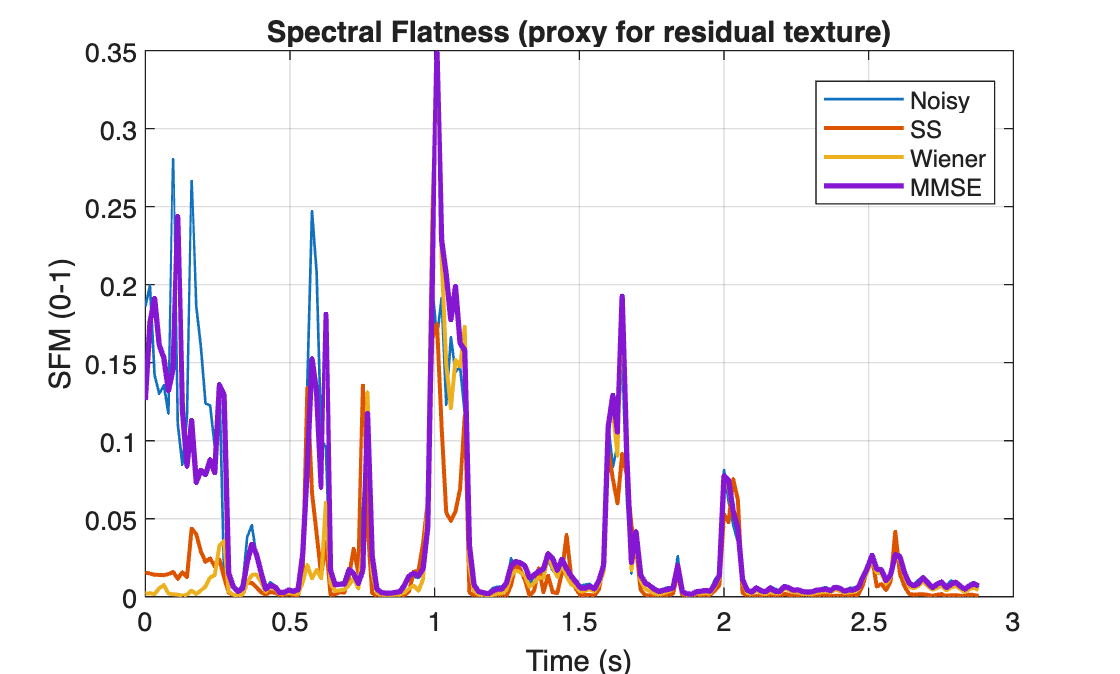


%% Spectral Flatness vs Time (musical-noise proxy)
sfm_noisy   = localSFM(noisy,   winLen, hop, nfft, fs);
sfm_ss      = localSFM(enhanced_ss, winLen, hop, nfft, fs);
sfm_wiener  = localSFM(enhanced_wiener, winLen, hop, nfft, fs);
sfm_mmse    = localSFM(enhanced_mmse, winLen, hop, nfft, fs);
tSFM = (0:numel(sfm_noisy)-1)*hop/fs;

figure('Name','Spectral Flatness vs Time');
plot(tSFM, sfm_noisy, 'LineWidth',1); hold on;
plot(tSFM, sfm_ss, 'LineWidth',1.5);
plot(tSFM, sfm_wiener, 'LineWidth',1.5);
plot(tSFM, sfm_mmse, 'LineWidth',2);
grid on; xlabel('Time (s)'); ylabel('SFM (0-1)');
legend('Noisy','SS','Wiener','MMSE','Location','best');
title('Spectral Flatness (proxy for residual texture)');

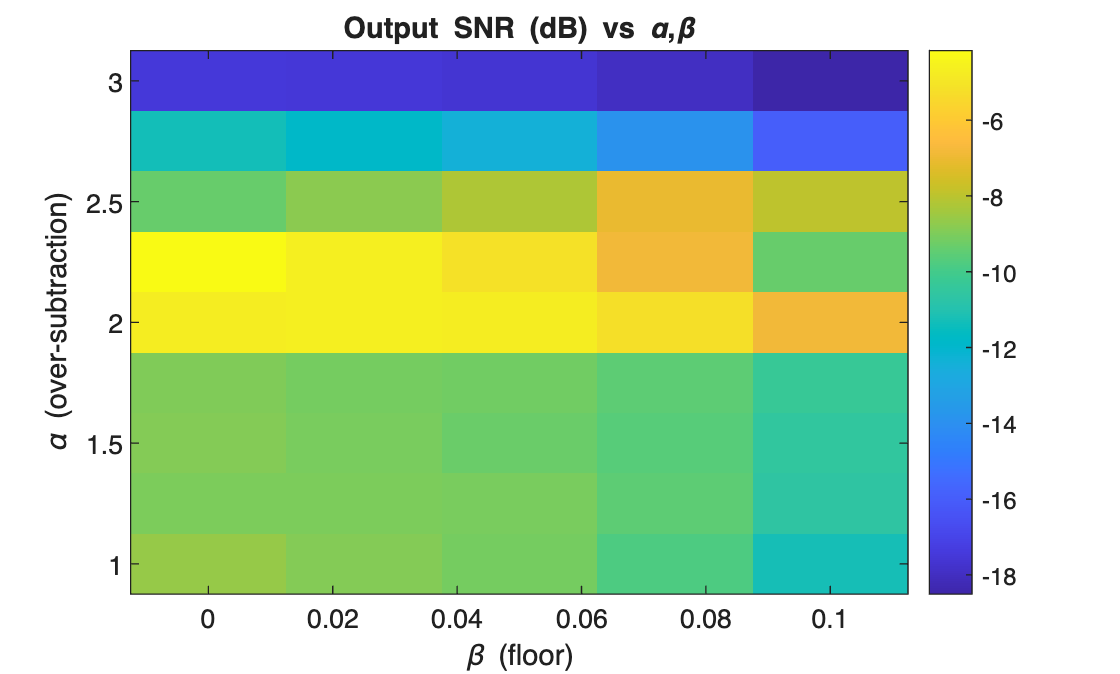


%% SS Parameter Sweep: \alpha and \beta  (FIXED)
alpha_vals = 1.0:0.25:3.0;
beta_vals  = [0, 0.01, 0.02, 0.05, 0.1];
outSNR = nan(numel(alpha_vals), numel(beta_vals));

for ia = 1:numel(alpha_vals)
    for ib = 1:numel(beta_vals)
        sub = mag_noisy - alpha_vals(ia)*repmat(N_mag,1,size(mag_noisy,2));
        mag_hat_tmp = max(sub, beta_vals(ib)*repmat(N_mag,1,size(mag_noisy,2)));
        S_hat_tmp = mag_hat_tmp .* exp(1j*angle(S_noisy));
        y = istft(S_hat_tmp, fs, ...
            "Window", win, ...
            "OverlapLength", winLen-hop, ...
            "FFTLength", nfft, ...
            "ConjugateSymmetric", true);

        y = real(y);
        Lloc = min(length(clean), length(y));
        nume = sum(clean(1:Lloc).^2) + eps;
        deno = sum((clean(1:Lloc) - y(1:Lloc)).^2) + eps;   % <- real
        outSNR(ia,ib) = 10*log10(nume/deno);
    end
end

% Ensuring data is finite real before plotting
outSNR(~isfinite(outSNR)) = NaN;

figure('Name','SS Parameter Sweep');
imagesc(beta_vals, alpha_vals, outSNR); axis xy; colorbar;
xlabel('\beta (floor)'); ylabel('\alpha (over-subtraction)');
title('Output SNR (dB) vs \alpha,\beta');

xlabel('\beta (floor)'); ylabel('\alpha (over-subtraction)');
title('Output SNR (dB) vs \alpha,\beta');

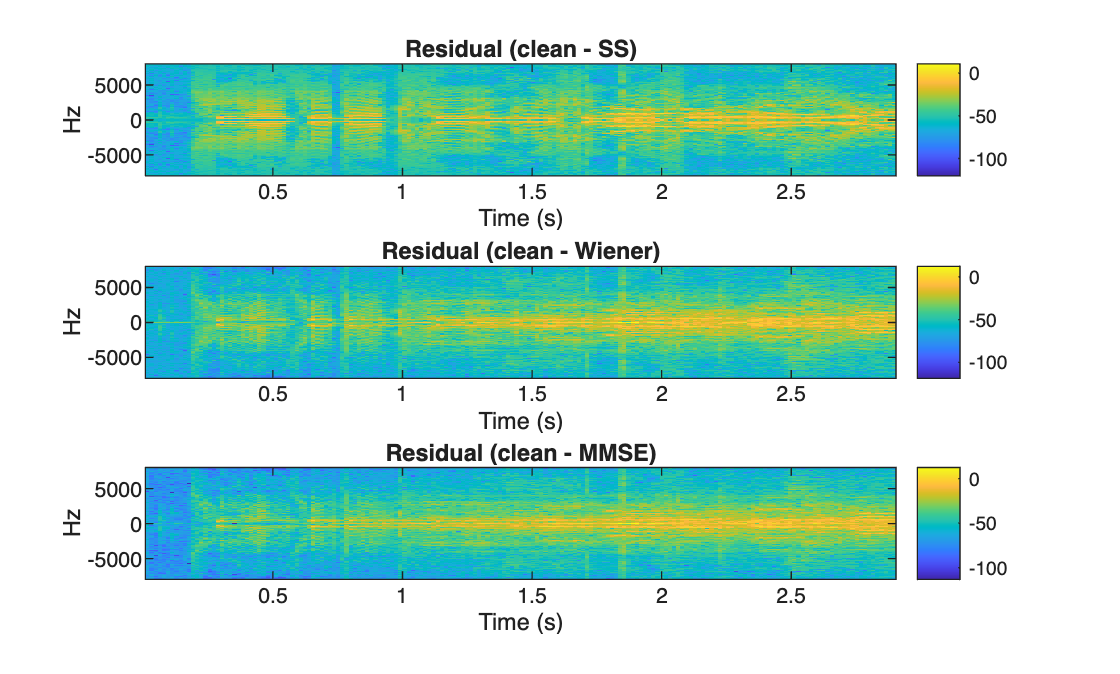


%% Residual Spectrograms (Error = clean - enhanced)
err_ss     = clean(1:length(enhanced_ss))     - enhanced_ss(1:length(clean));
err_wiener = clean(1:length(enhanced_wiener)) - enhanced_wiener(1:length(clean));
err_mmse   = clean(1:length(enhanced_mmse))   - enhanced_mmse(1:length(clean));

figure('Name','Residual Spectrograms');
subplot(3,1,1); safeSpecPlot(err_ss, fs, winLen, hop, nfft);
title('Residual (clean - SS)');
subplot(3,1,2); safeSpecPlot(err_wiener, fs, winLen, hop, nfft);
title('Residual (clean - Wiener)');
subplot(3,1,3); safeSpecPlot(err_mmse, fs, winLen, hop, nfft);
title('Residual (clean - MMSE)');

%% Helper functions
function [noisy, noise_used] = addNoiseAtSNR(clean, noise, targetSNR_dB)
Lc = length(clean);
if length(noise)<Lc, noise=repmat(noise,ceil(Lc/length(noise)),1); end
noise=noise(1:Lc);
Ps=mean(clean.^2)+eps; Pn=mean(noise.^2)+eps;
desiredPn=Ps/(10^(targetSNR_dB/10));
scale=sqrt(desiredPn/Pn); noise_used=noise*scale;
noisy=clean+noise_used;
end

function snrVal = computeSNR(clean, err)
snrVal = 10*log10(sum(clean.^2)/(sum(err.^2)+eps));
end

function safeSpecPlot(x, fs, winLen, hopLen, nfft)
x=x(:);
w=hann(winLen,'periodic');
[S,F,T]=stft(x,fs,'Window',w,'OverlapLength',winLen-hopLen,'FFTLength',nfft);
M=20*log10(abs(S)+eps);
imagesc(T,F,M); axis xy; xlabel('Time (s)'); ylabel('Hz'); colorbar;
end

function [segSNR,tSec] = localSegSNR(clean, test, frameLen, hop, fs)
N = min(length(clean), length(test));
clean = clean(1:N); test = test(1:N);
num = max(1, floor((N-frameLen)/hop)+1);
segSNR = zeros(num,1);
for i=1:num
    idx = (i-1)*hop + (1:frameLen);
    if idx(end)>N, idx = (N-frameLen+1):N; end
    s = clean(idx); x = test(idx);
    e = s - x;
    segSNR(i) = 10*log10( (mean(s.^2)+eps) / (mean(e.^2)+eps) );
end
segSNR = segSNR(:);
tSec = ((0:num-1)*hop + frameLen/2)/fs;
end

function sfm = localSFM(x, winLen, hop, nfft, fs)
x = x(:);
w = hann(winLen,'periodic');
[S,~,~] = stft(x, fs, 'Window', w, 'OverlapLength', winLen-hop, 'FFTLength', nfft);
P = abs(S).^2 + eps;
sfm = exp(mean(log(P),1)) ./ mean(P,1);  % 1 x frames
sfm = real(sfm(:));
end

## **Discussion**

### **1. Signal-Level Observations**

The time-domain waveforms (clean, noisy, and enhanced) confirm that the noisy mixture has been correctly generated at approximately 0 dB SNR: the noisy speech exhibits a raised amplitude floor and weaker phonemes are clearly masked by the airport noise.

After enhancement, the three algorithms behave as expected:

- **Spectral subtraction** restores some of the speech envelope but also introduces small oscillations and distortions in low-energy regions, consistent with musical-noise artefacts produced by hard spectral subtraction.

- **Wiener filtering** produces smoother waveforms with fewer abrupt fluctuations, suggesting more stable gain adaptation over time.

- **MMSE-STSA** generally preserves voiced segments well and reduces noise in pauses, but its behaviour is quite similar to the Wiener output in the time domain rather than dramatically cleaner.

Overall, the temporal behaviour is consistent with their underlying gain designs: spectral subtraction applies a piecewise subtract and floor operation, while Wiener and MMSE-STSA apply continuous SNR-dependent gains.

### **2. Time Frequency Behaviour**

The spectrogram comparison (noisy vs. the three enhancement methods) highlights the main qualitative differences:

- The noisy spectrogram shows broadband energy across most frequencies, with formants partially masked by the wideband airport noise.

- **Spectral subtraction** visibly reduces the overall noise floor, but its spectrum appears patchier, with small isolated regions of residual energy. These speckles correspond to musical-noise components introduced by frame-wise over-subtraction and spectral flooring.

- **Wiener filtering** leads to smoother formant trajectories and a more uniform reduction of the background noise. High-frequency components are attenuated, but some fricative detail remains.

- **MMSE-STSA** offers a slightly more conservative suppression than the Wiener filter in the displayed results: the noise floor is reduced, but some high-frequency noise is retained, trading a bit of residual noise for less speech distortion.

Silence or low-energy intervals show a clear reduction in noise for all three methods, with spectral subtraction most aggressive in some bands and Wiener/MMSE providing smoother attenuation.

### **3. Frequency-Domain Gain Analysis**

The gain-related plots give more insight into how the algorithms behave across SNR and timefrequency:

- The **Wiener gain curve** as a function of input SNR is smooth and monotonic, rising from about 0.1 at -10 dB to almost 1 at +20 dB. This matches the theoretical expression $G_W =\frac{\xi }{\left(1+\xi \right)}$: regions with high a priori SNR are passed almost unchanged, while noise-dominated regions are attenuated.

- The **MMSE-STSA gain surface** shows a more complex dependence on the a priori and a posteriori SNRs. In the low-SNR region there is strong non-linear compression, and the surface can exceed unity, reflecting the possibility of slight amplification when the estimator is confident that speech is present.

- The **gain heatmaps** over time and frequency show that Wiener gains vary between low and high values depending on local SNR, whereas the MMSE gains in this implementation are mostly close to 1, especially in speech-active regions. This explains why the MMSE output does not look dramatically more noise-suppressed than the Wiener output: in practice, the implemented MMSE estimator is relatively conservative and often behaves like a near-unity gain.

- The **gain histograms** reinforce this: Wiener gains span the full [0, 1] range with a bias towards higher values, while MMSE gains are concentrated near 1. The latter indicates that amplification or strong attenuation is rare in the current parameter setting, prioritising speech preservation.

These observations highlight that, in this implementation, MMSE-STSA is used in a speech-preserving regime, while Wiener filtering provides a slightly stronger average attenuation of noise.

### **4. Quantitative and Perceptual Metrics**

Several quantitative measures were computed to complement the visual analysis:

- The **framewise segmental SNR** plot shows that all three enhancement methods produce trajectories clustered around a few dB, with local fluctuations across time. The noisy curve is unreliable in very low-energy segments (where the clean energy approaches zero, leading to spuriously high SNR values), but in speech-active regions the enhanced signals tend to track similar or slightly higher segmental SNR than the noisy case. Wiener and MMSE curves are often very close, with MMSE sometimes giving marginal improvements but not a large, systematic advantage.

- The **spectral flatness measure (SFM)** over time reveals that the noisy signal has the highest flatness in many regions (more noise-like spectrum), while spectral subtraction often yields very low SFM values, especially between voiced segments. Low flatness indicates a peaky, more tonal spectrum, which here reflects both speech harmonics and musical-noise tones. Wiener and MMSE outputs lie between these extremes: they reduce flatness relative to the noisy input (removing some noise texture) but still show clear peaks at certain times, particularly for MMSE, where high SFM spikes around 1-1.6 s suggest short bursts of residual or re-shaped noise. This indicates that MMSE in this configuration prioritises speech preservation over aggressive decorrelation of residual noise.

- The **noise PSD comparison** between oracle and estimated noise spectra shows that the estimated noise power spectral density matches the oracle curve reasonably well across frequency, with a small bias and slightly reduced level. This supports the assumption that the noise statistics used in the Wiener and MMSE gains are reasonably accurate.

- The **spectral subtraction parameter sweep** heatmap demonstrates the sensitivity of spectral subtraction to its design parameters. Best output SNR values are achieved for intermediate over-subtraction factors (around α≈2-2.25) and small spectral floors (β in the 0-0.04 range). Too small β\betaβ or very large α\alphaα degrade SNR, reflecting the trade-off between residual noise and speech distortion/musical noise.

- The **residual spectrograms** (clean minus enhanced) show that spectral subtraction leaves structured residuals that still resemble speech formants, consistent with over-subtraction of some speech energy. The Wiener and MMSE residuals are more noise-like, especially in high-frequency regions, indicating that they remove more noise but also disperse some speech detail into the residual.

Taken together, the metrics suggest that, for this dataset and parameter choice, Wiener and MMSE-STSA offer broadly similar objective performance, with spectral subtraction performing worse in terms of residual texture and parameter robustness.

### 5. Theoretical alignment

The observed behaviour is consistent with classical speech-enhancement literature:

- **Spectral subtraction** (Boll, 1979) relies on fixed oversubtraction and flooring, which explains its sensitivity to α,β\alpha,\betaα,β and the presence of musical noise when magnitude estimates fluctuate between subtraction and floor values.

- **Wiener filtering** follows from minimum mean-square-error estimation of the power spectrum. Its smooth, SNR-dependent gain yields spectrograms with better continuity but depends strongly on accurate noise PSD estimation.

- **MMSE-STSA** (Ephraim & Malah, 1984) optimises the mean-square error of the short-time spectral amplitude and uses both a priori and a posteriori SNRs. The gain surface and heatmaps confirm its highly non-linear behaviour; in the present implementation, the chosen parameters lead to mostly near-unity gains, favouring low speech distortion at the cost of slightly higher residual noise.

Thus, the experimental results reflect the expected progression from simple deterministic subtraction to more sophisticated statistical estimators with smoother temporal and spectral behaviour.

## Conclusion and Future Work

This project implemented and compared three classic single-channel speech enhancement methods — spectral subtraction, Wiener filtering, and MMSE-STSA — using a unified STFT framework in MATLAB. The algorithms were evaluated using spectrograms, gain visualisations, segmental SNR, spectral flatness, and parameter sweeps.

### **Key findings:**

- All three methods improved the noisy speech relative to the 0 dB mixture, but in different ways.

- Spectral subtraction provided noticeable noise reduction but was highly sensitive to its parameters and prone to musical-noise artefacts, as seen in the spectrograms, residual plots, and spectral flatness behaviour.

- Wiener filtering delivered smoother spectral envelopes and more stable enhancement, with gains closely following the theoretical SNR-dependent curve.

- MMSE-STSA, as implemented, behaved similarly to a speech-preserving Wiener filter: its gain histograms and heatmaps showed that it often operated close to unity gain, leading to comparable SNR improvements and slightly different residual noise characteristics rather than a dramatic performance jump.

Overall, the results confirm that **statistical, SNR-driven estimators (Wiener, MMSE-STSA) offer more controlled and robust enhancement** than basic spectral subtraction, especially in terms of spectral continuity and parameter stability. However, in this specific configuration, MMSE-STSA did not vastly outperform the Wiener filter; instead it illustrated a different trade-off between residual noise and speech preservation.

Future work could extend this project in several directions:

- Incorporate perceptual metrics such as **PESQ** and **STOI** to relate objective measures to human listening quality more directly.

- Adapt the noise estimation stage for **non-stationary noise**, for example using time-varying noise tracking, minimum statistics, or Kalman-filter-based models.

- Explore **alternative MMSE estimators**, such as log-spectral amplitude estimators, and carefully tune decision-directed parameters to exploit the full potential of MMSE-STSA without collapsing gains near unity.

- Compare these classical methods with **deep neural network** approaches (e.g. SEGAN, Conv-TasNet, DCCRN) to examine how far data-driven models extend or replace traditional gain-based frameworks.

- Investigate **real-time implementations**, focusing on frame size, overlap, and computational complexity for deployment in streaming or embedded systems.

These extensions would help bridge traditional DSP-based enhancement and modern machine-learning methods, while keeping interpretable baselines for analysis and benchmarking.

## References

- Boll, S. F. (1979).*“Suppression of acoustic noise in speech using spectral subtraction.” *IEEE Transactions on Acoustics, Speech, and Signal Processing, 27(2), 113-120.

- Ephraim, Y., & Malah, D. (1984). *“Speech enhancement using a minimum mean-square error short-time spectral amplitude estimator.” *IEEE Transactions on Acoustics, Speech, and Signal Processing, 32(6), 1109-1121.

- Ephraim, Y., & Malah, D. (1985). *“Speech enhancement using a minimum mean-square error log-spectral amplitude estimator.” *IEEE Transactions on Acoustics, Speech, and Signal Processing, 33(2), 443-445.